[nc, fs] = audioread('audio_experiments/mics_nc.wav');
[foam, fs] = audioread('audio_experiments/mics_foam.wav');

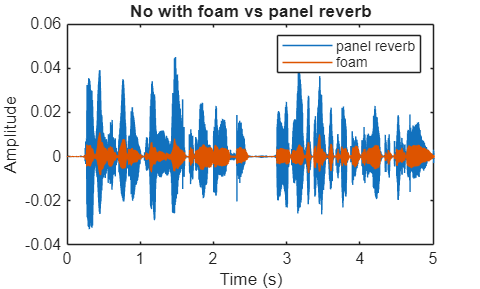

t = (0:length(foam(:, 1)) - 1) / fs;

figure
plot(t, nc(:, 1))
hold on
plot(t, foam(:, 1))
legend('panel reverb', 'foam')
title('No with foam vs panel reverb')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([t(1), t(end)])

target = nc(:, 1);
ref = nc(:, 2);

cutoff = 400;
target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);

source_to_ref = 2;
ir_len = 128;
filter_order = 2 * ir_len;
step_size = 0.9;

panel_ir = clipped_irs(ir_len, source_to_ref);
panel_ir = highpass(panel_ir, cutoff, fs);

[ref_norm, factor, target_norm] = normalize_data(ref, target);

fxlms = FxLMS(ref_norm, target_norm, panel_ir, filter_order, step_size, false);
[pred, mses] = fxlms.learn(10);
pred = denormalize_data(pred, factor);
mses = mses * factor^2;

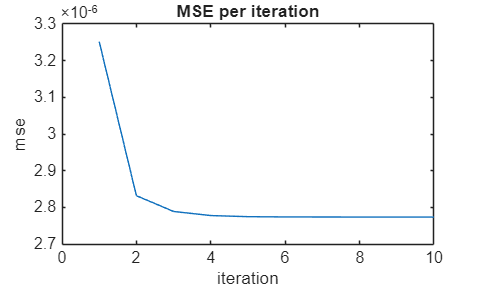

figure
plot(mses)
title('MSE per iteration')
xlabel('iteration')
ylabel('mse')

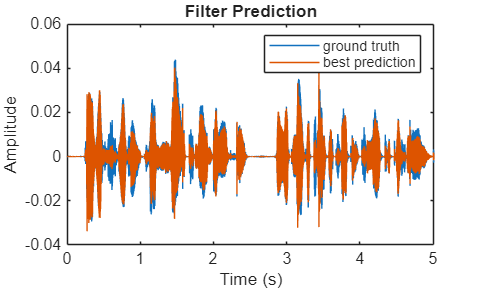

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, pred);
legend("ground truth", "best prediction")

title("Filter Prediction")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

cancel_wav = denormalize_data(fxlms.ref_filt, factor);

save_cancel_clip(-cancel_wav, 'same_session');

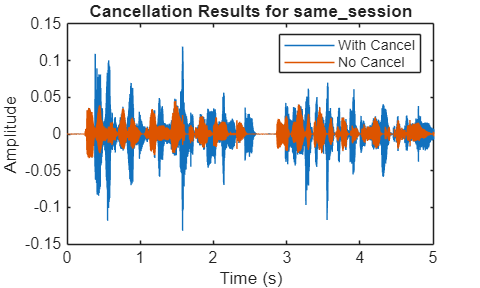

c = CancelAnalysis('same_session');
c.plot_cancel_results();

save_cancel_clip(cancel_wav, 'same_session');

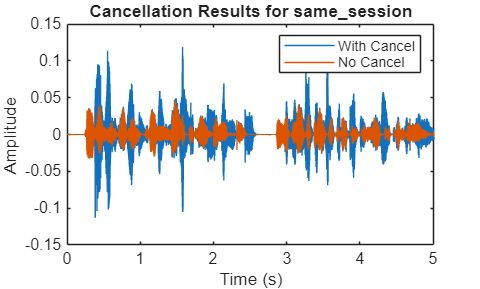

c = CancelAnalysis('same_session');
c.plot_cancel_results();

target = nc(:, 1) - foam(:, 1);
ref = nc(:, 2);

cutoff = 400;
target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);

source_to_ref = 2;
ir_len = 128;
filter_order = 2 * ir_len;
step_size = 0.9;

panel_ir = clipped_irs(ir_len, source_to_ref);
panel_ir = highpass(panel_ir, cutoff, fs);

[ref_norm, factor, target_norm] = normalize_data(ref, target);

fxlms = FxLMS(ref_norm, target_norm, panel_ir, filter_order, step_size, false);
[pred, mses] = fxlms.learn(10);
pred = denormalize_data(pred, factor);
mses = mses * factor^2;

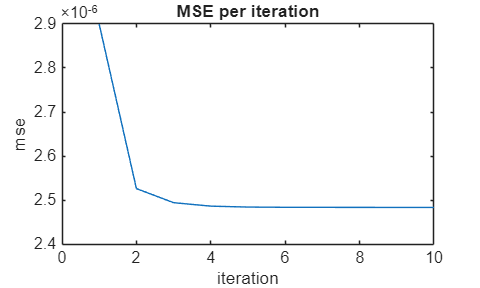

figure
plot(mses)
title('MSE per iteration')
xlabel('iteration')
ylabel('mse')

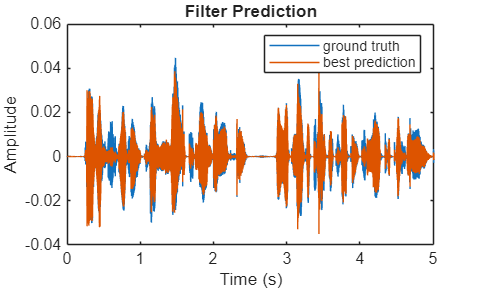

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, pred);
legend("ground truth", "best prediction")

title("Filter Prediction")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

cancel_wav = denormalize_data(fxlms.ref_filt, factor);

save_cancel_clip(-cancel_wav, 'same_session');

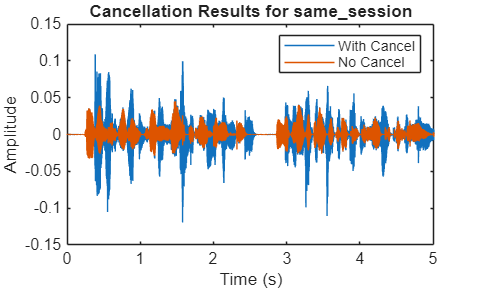

c = CancelAnalysis('same_session');
c.plot_cancel_results();

save_cancel_clip(cancel_wav, 'same_session');

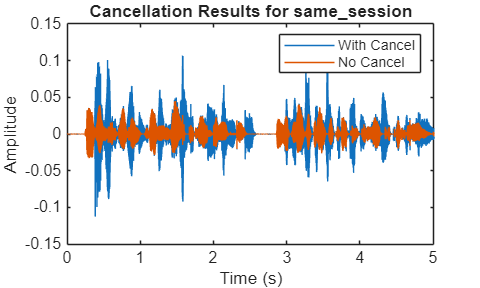

c = CancelAnalysis('same_session');
c.plot_cancel_results();

size(pred)

ans =            1      240640


size(cancel_wav)

ans =       240640           1


save_cancel_clip(-pred', 'same_session');

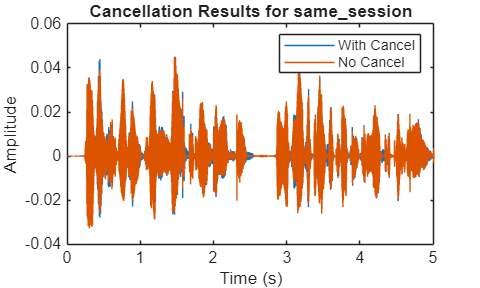

c = CancelAnalysis('same_session');
c.plot_cancel_results();